clear;
tic;
%符号参数
syms ll lwl lbl;
syms lr lwr lbr;
%syms mw mb ml;
syms Iw Ill Ilr;
%syms Ib Iz;
%syms Rw Rl lc;
%syms g;

syms theta_wl theta_wr;
syms theta_wld theta_wrd;
syms theta_wldd theta_wrdd;

% 定义状态变量
syms s phi theta_ll theta_lr theta_b;
syms sd phid theta_lld theta_lrd theta_bd;
syms sdd phidd theta_lldd theta_lrdd theta_bdd;
% 定义控制输入
syms T_lwl T_lwr T_bll T_blr mw mb ml Iw Ib Iz Ill Ilr eta_l  lwl lbl lbr lwr Rw Rl lc; 


%}
%{
% 仿真参数
% 轮子、机体、腿的质量
mw = 1;
mb = 18.3393;
ml = 0.924;
% 轮子、机体的转动惯量
Iw = 0.004;
Ib = 0.2356;
Iz = 1.0167;
% 腿转动惯量
Ill = 0.1785 * ll * ll + 0.03;
Ilr = 0.1785 * lr * lr + 0.03;
% 左腿长
eta_l = 0.4406;
lwl = eta_l * ll + 0.016;
lbl = ll - lwl;
% 右腿长
lbr = lbl;
lwr = lwl;
% 轮子半径和半轮距
Rw = 0.06;
Rl = 0.18;
lc = -0.02;
%}
% 重力加速度
g = 9.80665;

% 定义微分方程组(已化简)
eqns = [(Iw * ll / Rw + mw * Rw * ll + ml * Rw * lbl) * theta_wldd + (ml * lwl * lbl - Ill) * theta_lldd + (ml * lwl + 0.5 * mb * ll) * g * theta_ll + T_bll - T_lwl * (1 + ll / Rw) == 0;
        (Iw * lr / Rw + mw * Rw * lr + ml * Rw * lbr) * theta_wrdd + (ml * lwr * lbr - Ilr) * theta_lrdd + (ml * lwr + 0.5 * mb * lr) * g * theta_lr + T_blr - T_lwr * (1 + lr / Rw) == 0;
    - (mw * Rw ^ 2 + Iw + ml * Rw ^ 2 + 0.5 * mb * Rw ^ 2) * theta_wldd - (mw * Rw ^ 2 + Iw + ml * Rw ^ 2 + 0.5 * mb * Rw ^ 2) * theta_wrdd - (ml * Rw * lwl + 0.5 * mb * Rw * ll) * theta_lldd - (ml * Rw * lwr + 0.5 * mb * Rw * lr) * theta_lrdd + T_lwl + T_lwr == 0;
    (mw * Rw * lc + Iw * lc / Rw + ml * Rw * lc) * theta_wldd + (mw * Rw * lc + Iw * lc / Rw + ml * Rw * lc) * theta_wrdd + ml * lwl * lc * theta_lldd + ml * lwr * lc * theta_lrdd - Ib * theta_bdd + mb * g * lc * theta_b - (T_lwl + T_lwr) * lc / Rw - (T_bll + T_blr) == 0;
    (0.5 * Iz * Rw / Rl + Iw * Rl / Rw) * theta_wldd - (0.5 * Iz * Rw / Rl + Iw * Rl / Rw) * theta_wrdd + 0.5 * Iz * ll / Rl * theta_lldd - 0.5 * Iz * lr / Rl * theta_lrdd - T_lwl * Rl / Rw + T_lwr * Rl / Rw == 0;
    ];

% 求解微分方程组
[theta_lldd, theta_lrdd, theta_bdd, theta_wldd, theta_wrdd] = solve(eqns, [theta_lldd, theta_lrdd, theta_bdd, theta_wldd, theta_wrdd]);

% 定义s与phi的微分方程
sdd = (Rw / 2) * (theta_wldd + theta_wrdd);
phidd = (Rw / (2 * Rl)) * (-theta_wldd + theta_wrdd) - ll / (2 * Rl) * theta_lldd + lr / (2 * Rl) * theta_lrdd;

% 计算雅可比矩阵
Ja = jacobian([sd sdd phid phidd theta_lld theta_lldd theta_lrd theta_lrdd theta_bd theta_bdd], [s sd phi phid theta_ll theta_lld theta_lr theta_lrd theta_b theta_bd]);
Jb = jacobian([sd sdd phid phidd theta_lld theta_lldd theta_lrd theta_lrdd theta_bd theta_bdd], [T_lwl T_lwr T_bll T_blr]);
A = vpa(subs(Ja, [s sd phi phid theta_ll theta_lld theta_lr theta_lrd theta_b theta_bd], [s 0 phi 0 0 0 0 0 0 0]))

B = vpa(subs(Jb, [s sd phi phid theta_ll theta_lld theta_lr theta_lrd theta_b theta_bd], [s 0 phi 0 0 0 0 0 0 0]))

% A,B矩阵为数值矩阵才能进行后续计算

% 腿长变化范围
ll_s = 0.10:0.005:0.4;
lr_s = ll_s;

% 存放不同L对应的K
Ks = zeros(4, 10, length(ll_s) * length(lr_s));

% 定义权重矩阵Q, R
Q = diag([500 100 50 5 1 1 1 1 1000 1]);
R = diag([1 1 0.25 0.25]);

A_calc = matlabFunction(A);
B_calc = matlabFunction(B);
matlabFunction(A, 'File', 'function/A_mat');
matlabFunction(B, 'File', 'function/B_mat');

for step_l = 1:length(ll_s)
    
    parfor step_r = 1:length(lr_s) % 强大的并行计算(*^▽^*)
        
        % 变量替换为数字
        A_ = A_calc(ll_s(step_l), lr_s(step_r));
        B_ = B_calc(ll_s(step_l), lr_s(step_r));
        
        %{
        % 检查系统是否可控
        if rank(ctrb(A_, B_)) ~= size(A_, 1)
            disp('系统不可控');
        end
        %}
        
        % 离散化
        [G, H] = c2d(A_, B_, 0.001); %1000Hz
        
        % 求解反馈矩阵K
        Ks(:, :, step_r, step_l) = dlqr(G, H, Q, R);
        % Ks(:, :, step_r, step_l) = lqr(A_, B_, Q, R);
        
    end
    
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 16 workers.



save('data/Ks.mat', 'Ks');
disp('LQR计算完成，准备进行拟合');

LQR计算完成，准备进行拟合


%% 拟合部分

% 初始化一个符号矩阵，用于存储拟合结果
fitresult_matrix = sym('fitresult', [4 10]);
rsquare_values = zeros(4, 10);
fit_funcs = cell(4, 10);
% 定义符号变量
K = sym('K', [4 10]);
syms Ll Lr x y;

for i = 1:4
    
    for j = 1:10
        % 准备拟合所需的数据
        K_data = squeeze(Ks(i, j, :, :));
        K_data = K_data(1:length(ll_s), 1:length(lr_s));
        K_data = K_data.';
        [ll_data, lr_data] = meshgrid(ll_s, lr_s);
        xData = ll_data(:);
        yData = lr_data(:);
        zData = K_data(:);
        
        % 进行拟合
        ft = fittype('poly44');
        [fit_result, gof] = fit([xData, yData], zData, ft);
        % R方
        rsquare_values(i, j) = gof.rsquare;
        % 存储拟合结果
        K(i, j) = str2sym(formula(fit_result));
        K(i, j) = subs(K(i, j), coeffnames(fit_result).', coeffvalues(fit_result));
        K(i, j) = subs(K(i, j), [x y], [Ll Lr]);
        
        
        %绘制拟合图
        % fitted_values = fit_result(xData, yData);
        % figure;
        % scatter3(xData, yData, zData, 'b.');
        % hold on;
        % surf(ll_data, lr_data, reshape(fitted_values, size(ll_data)), 'FaceAlpha', 0.5);
        % xlabel('L_l');
        % ylabel('L_r');
        % zlabel('K');
        % title('Fitted Surface');
        % hold off;
        
    end
    
end

disp('R方');

R方


disp(rsquare_values);

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999
    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    1.0000    1.0000
    0.9999    0.9998    1.0000    1.0000    0.9999    0.9998    1.0000    1.0000    1.0000    1.0000




% 输出到m函数
matlabFunction(K, 'File', 'function/LQR_k');

Ll = 0.2; Lr = 0.2;
K = LQR_k(Ll, Lr);
disp('LQR数据  L=0.2');

LQR数据  L=0.2


disp(K);

  -11.6983   -9.9489   -2.8324   -0.8987  -16.5277   -2.3048   -9.6206   -1.4943  -13.0977   -2.1076
  -11.7011   -9.9509    2.8328    0.8989   -9.6249   -1.4945  -16.5286   -2.3051  -13.0974   -2.1077
   17.9833   13.5847   -8.1308   -3.2634   25.9851    3.1266   -1.1476    1.1188  -35.5501   -2.6723
   17.9835   13.5849    8.1297    3.2630   -1.1460    1.1193   25.9855    3.1266  -35.5605   -2.6725



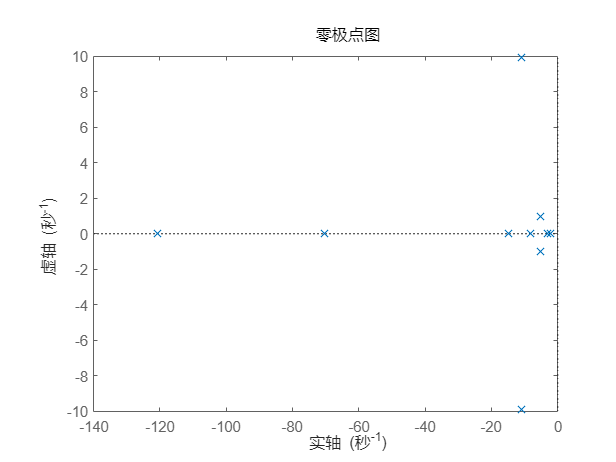

C=eye(10);
D=zeros(10,4);
sys1 = ss(A_calc(Ll,Lr)-B_calc(Ll,Lr)*K,B_calc(Ll,Lr),C,D);
%step(sys1);
pzmap(sys1);

toc;

历时 43.790614 秒。


save("data/sys.mat");
disp('记得检查leg_calc腿长是否设置正确');

记得检查leg_calc腿长是否设置正确
